Separar en datos "train" (impares) y datos "validation" (pares)

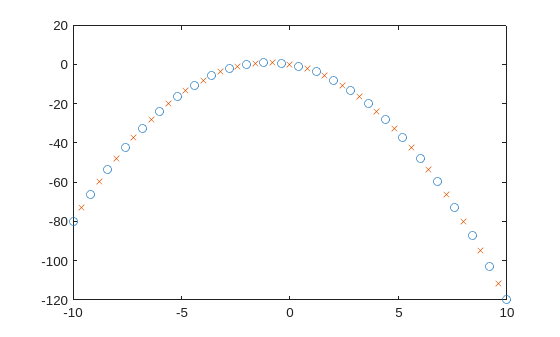

n_puntos = 51;
x = linspace(-10,10,n_puntos)';

y = -2*x-x.^2;

data = [x y];

trndata = data(1:2:n_puntos,:);  % impares -> train
chkdata = data(2:2:n_puntos,:);  % pares  -> validation

figure;

plot(trndata(:,1), trndata(:,2),'o'); hold on;
plot(chkdata(:,1), chkdata(:,2),'x');

Crear FIS

numMFs  = 5;
mfType  = 'gbellmf';     % campana generalizada

fismat = genfis1(trndata, numMFs, mfType);

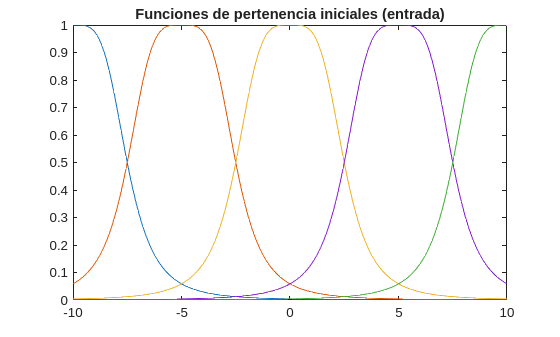

figure;
[xmf, ymf] = plotmf(fismat,'input',1);
plot(xmf, ymf);
title('Funciones de pertenencia iniciales (entrada)');

Entrenar FIS con ANFIS

numEpochs = 40;

[fismat1, trnErr, ss, fismat2, chkErr] = anfis(trndata, fismat, numEpochs, NaN, chkdata);


ANFIS info:
	Number of nodes: 24
	Number of linear parameters: 10
	Number of nonlinear parameters: 15
	Total number of parameters: 25
	Number of training data pairs: 26
	Number of checking data pairs: 25
	Number of fuzzy rules: 5


Start training ANFIS ...

1 	 1.11156 	 1.10165
2 	 1.10659 	 1.0966
3 	 1.10161 	 1.09154
4 	 1.09662 	 1.08647
Step size increases to 0.011000 after epoch 5.
5 	 1.09163 	 1.08139
6 	 1.08663 	 1.07631
7 	 1.08112 	 1.07071
8 	 1.0756 	 1.06511
Step size increases to 0.012100 after epoch 9.
9 	 1.07007 	 1.0595
10 	 1.06453 	 1.05387
11 	 1.05843 	 1.04768
12 	 1.05233 	 1.04149
Step size increases to 0.013310 after epoch 13.
13 	 1.04621 	 1.03528
14 	 1.04008 	 1.02907
15 	 1.03333 	 1.02222
16 	 1.02657 	 1.01538
Step size increases to 0.014641 after epoch 17.
17 	 1.0198 	 1.00852
18 	 1.01303 	 1.00165
19 	 1.00557 	 0.994098
20 	 0.998093 	 0.986535
Step size increases to 0.016105 after epoch 21.
21 	 0.990612 	 0.978966
22 	 0.983124 	 0.971392
23 

Comprobar RMSE en datos

epoch = 1:numEpochs;

trnOut = evalfis(trndata(:,1), fismat1);        % Comprobar "Train"

trnRMSE = norm(trnOut - trndata(:,2))/sqrt(length(trnOut))

trnRMSE = 0.8057


chkOut = evalfis(chkdata(:,1), fismat2);        % Comprobar "Val"

chkRMSE = norm(chkOut - chkdata(:,2))/sqrt(length(chkOut))

chkRMSE = 0.7926

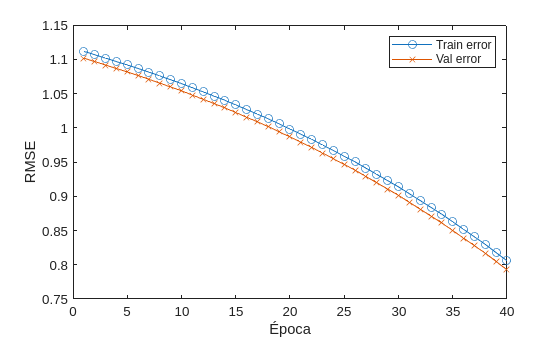


plot(epoch, trnErr, 'o-');
hold on;
plot(epoch, chkErr, 'x-');
hold off
xlabel('Época');
ylabel('RMSE');
legend('Train error','Val error');

Tamaño del Paso del Gradiente

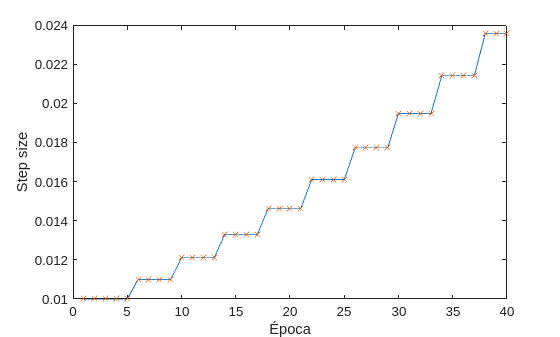

plot(epoch, ss,'-'); 
hold on;
plot(epoch, ss,'x');
hold off
xlabel('Época'); ylabel('Step size');

Funciones de Pertenencia después del entrenamiento

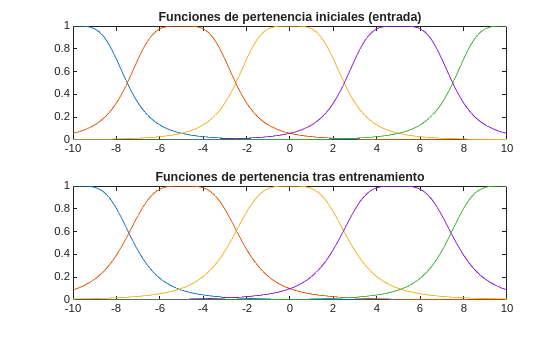

figure;
[xmf2, ymf2] = plotmf(fismat1,'input',1);
subplot(2,1,1)
plot(xmf, ymf);
title('Funciones de pertenencia iniciales (entrada)');
subplot(2,1,2)
plot(xmf2, ymf2);
title('Funciones de pertenencia tras entrenamiento');

Resultados

anfis_y = evalfis(x, fismat1);

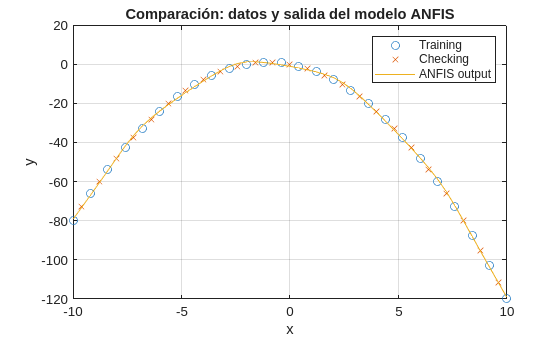


figure;
plot(trndata(:,1), trndata(:,2),'o'); hold on;
plot(chkdata(:,1), chkdata(:,2),'x');
plot(x, anfis_y,'-');
grid on;
legend('Training','Checking','ANFIS output');
xlabel('x'); ylabel('y');
title('Comparación: datos y salida del modelo ANFIS');

anfis_y_init = evalfis(x, fismat);

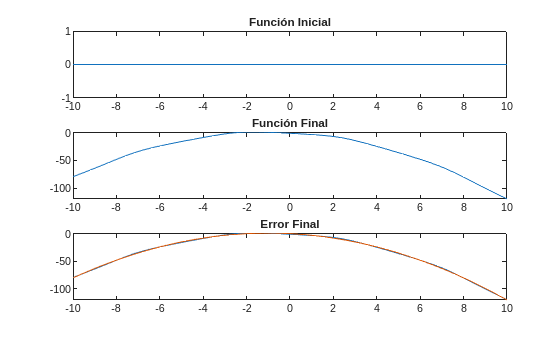


figure;
subplot(3,1,1)
plot(x, anfis_y_init,'-');
title('Función Inicial');
subplot(3,1,2)
plot(x, anfis_y,'-');
title('Función Final');
subplot(3,1,3)
plot(x, anfis_y,'-');
hold on;
plot(x, y,'-');
hold off;
title('Error Final');